# ***DSP HW1 Software Assignment***

## ***Dr.Shamsollahi***

#### ***MohammadParsa Dini 400101204***

***Part 1:***

***1.1***

we are given an LTI system of order 3 with characteristic equation: 


$$y[n] = 0.0181x[n] + 0.0543x[n - 1] + 0.0543x[n - 2] + 0.0181x[n - 3] +1.76y[n - 1] - 1.1829y[n - 2] + 0.2781y[n - 3]$$


which by taking Z transform will imply that:


$$H(z) = \frac{Y(z)}{X(z)} = \frac{0.0181 + 0.0543 z^{-1} +0.0543 z^{-2} + 0.0181 z^{-3}}{ 1 - 1.76 z^{-1} + 1.183 z^{-2} - 0.2781 z^{-3}}$$
 

Now we will plot the roots and zeros of $H(z)$ besides its frequency response:

clear;
clc;
denom = [1,- 1.76,1.1829,-0.2781];
num = [0.0181,0.0543,0.0543,0.0181];
ts = 0.001;
H_z = tf(num, denom, ts,'Variable','z^-1')

H_z =
 
  0.0181 + 0.0543 z^-1 + 0.0543 z^-2 + 0.0181 z^-3
  ------------------------------------------------
      1 - 1.76 z^-1 + 1.183 z^-2 - 0.2781 z^-3
 
Sample time: 0.001 seconds
Discrete-time transfer function.



here is the frequency response:

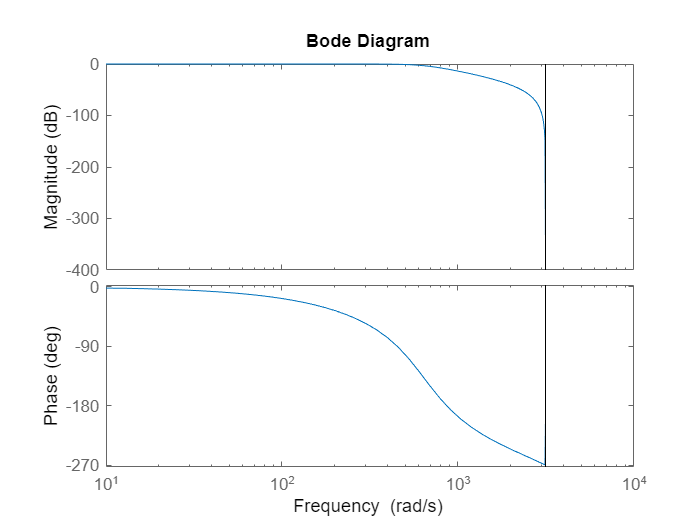

figure();
bode(H_z)

by using pole() function for $H(z)$ and $H^{-1}(z)$  we can find poles and roots.

here are the roots/poles:

P = pole(H_z)

P =    0.6252 + 0.3935i
   0.6252 - 0.3935i
   0.5097 + 0.0000i


here are the zeros:

R = pole(H_z^(-1))

R =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


The grid spans the range of angles from 0 to 360 degrees (in steps of 0.5 degrees, converted to radians) and the range of values from -1.5 to 1.5 (in steps of 0.005). 

The `pol2cart` function converts the polar coordinates (angles and radii) obtained from the meshgrid into Cartesian coordinates $(X, Y)$.

The Cartesian coordinates obtained are used to create a complex number $Z$, where $Z = X + iY$ . eventually we do the plotting.

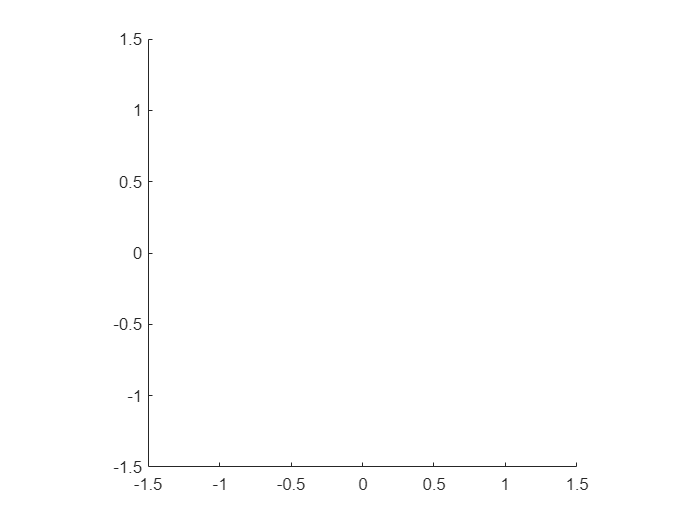

% covering all pointswithin a circle of radius 'r'
[th,r] = meshgrid((0:0.5:360)*pi/180,-1.5:.005:1.5);
% converting from polar to cartesian  
[X,Y] = pol2cart(th,r);
% this is the z-plane
Z = X+1i*Y;
% this is our Transfer function in z-domain
W =(1 - 1.76.*Z.^(-1) + 1.183.*Z.^(-2) - 0.2781.*Z.^(-3))./(0.0181 + 0.0543.*Z.^(-1)  + 0.0543.*Z.^(-2) + 0.0181.*Z.^(-3));
figure();
dcolor(X,Y,W)
axis square

% attention: we have used this function'dcolor':
% and we got assistance from this url:
% https://www.mathworks.com/matlabcentral/fileexchange/29028-dcolor#:~:text=DCOLOR%20uses%20a%20coloring%20function,handle%20as%20the%20source%20data.

As we take a deep look into the output, we can deduce that  the zeros are shown as dark holes and it's poles are connected to zeros with 

sky blue colored paths, which is similiar to the zeros and holes of the transfer funtion.

using impz we can compute and plot the impulse response of a discrete-time system defined by its transfer function.

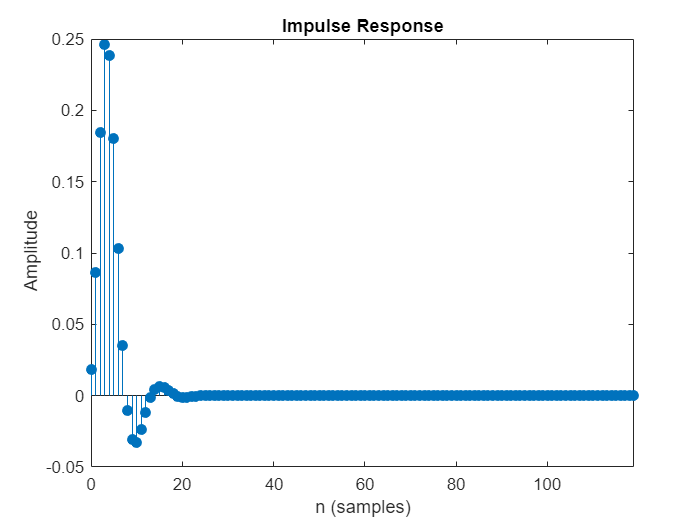

figure();
impz(num,denom,120)

***Part 2:***

The chirp signal is defined as $c(t) = \cos( \pi \mu t^2 + 2\pi f_1 t + \psi)$ 

clear;
f_interval = 25e-3 * 600000;
display(f_interval)

f_interval = 15000

As we are told, we sample the chirp signal with $8000 Hz$ sampling rate. As we know, the signal has maximum $15kHz$ frequency.

Thus, in order to have the signal without alising we should sample our signal with $30kHz$ rate.

***(I)*** Here is the result of $f_s = 8000Hz
$ case:

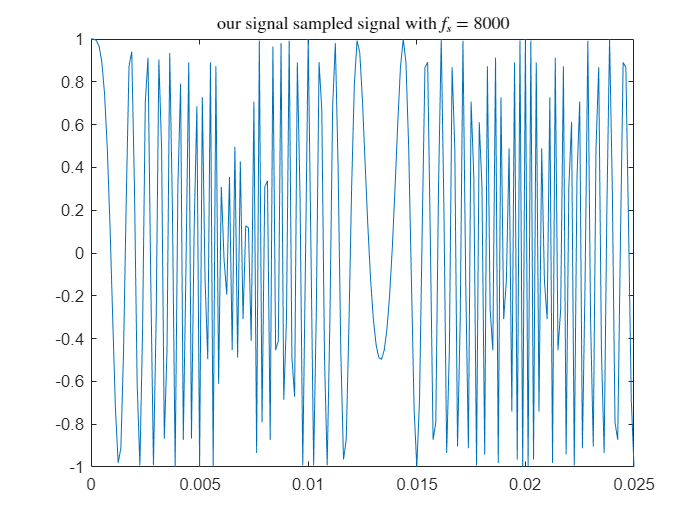

fs = 8000;
Ts = 1/fs;
f1 = 0;
t_f = 0.05;
mu = 600000;
t = 0:Ts:0.025;
t_disc = 0:Ts:t_f;
chirp_signal = cos(pi*mu*t.^2 + 2*pi*f1*t);
figure();
plot(t, chirp_signal);
title('our signal sampled signal with $f_s = 8000$',Interpreter='latex');

***(II)*** Here is the result of $f_s = 30kHz
$ case:

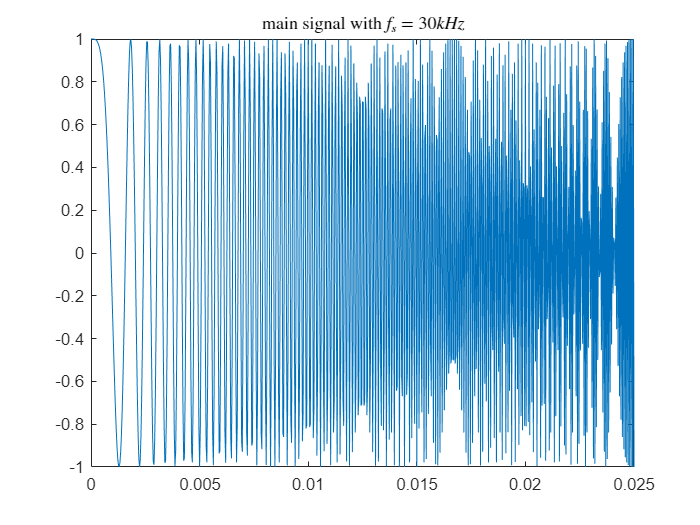

warning('off');
fs = 30000;
f1 = 0;
mu = 600000;
t = 0:1/fs:0.025;
figure();
chirp_signal = cos(pi*mu*t.^2 + 2*pi*f1*t);
plot(t, chirp_signal);
title('main signal with $f_s=30kHz$','interpreter','latex')

lets take a closer look at the signal in te 30kHz case:

and we will dive into the place with high frequency components such as [.02, 0.025] time interval.

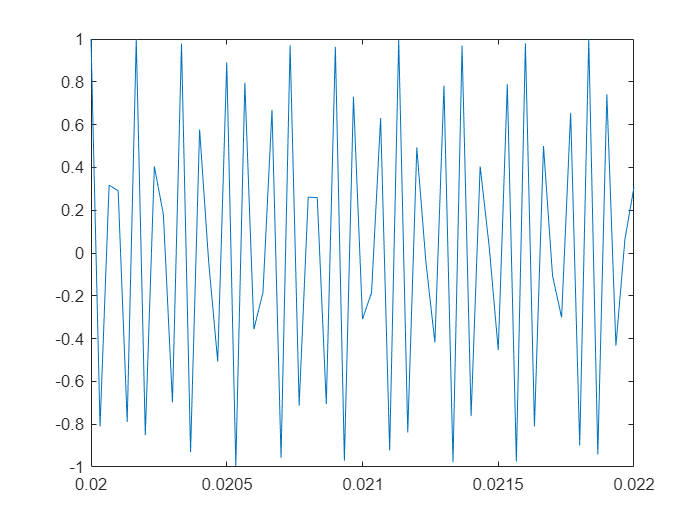

figure();
fs = 30000;
f1 = 0;
mu = 600000;
t = 0:1/fs:0.022;
figure();
chirp_signal = cos(pi*mu*t.^2 + 2*pi*f1*t);
plot(t, chirp_signal);
xlim([0.02 0.022]);

we will depict the sampled signal besides its original source: in the secind case we will increase the frequency of

sampling to see the differences.

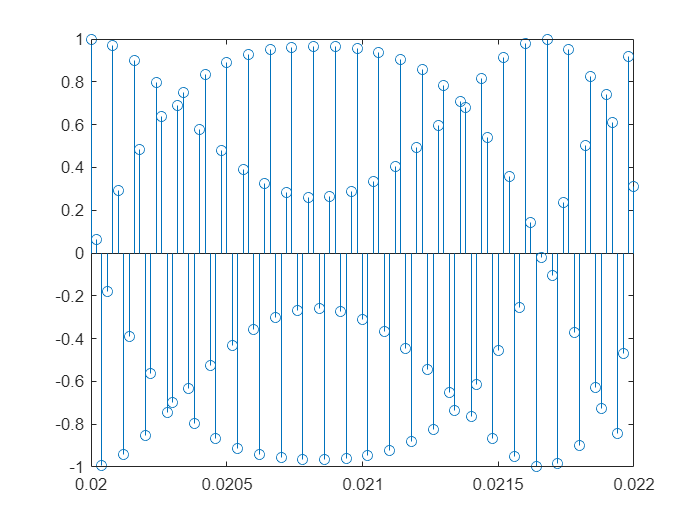

f1 = 0;
mu = 600000;
figure();

%subplot(1,2,1);
%fs = 8000;
%tt = 0:02:1/fs:0.025;
%chirp_signal = cos(pi*mu*tt.^2 + 2*pi*f1*tt);
%stem(tt, chirp_signal);

%subplot(1,2,2); 
fs_ = 50000; % new sampling frequency
tt_ = 0.02:1/fs_:0.022;
chirp_signal_ = cos(pi*mu*tt_.^2 + 2*pi*f1*tt_);
stem(tt_, chirp_signal_);

So we better increase the sampling rate to decrease the error.

***Part 3:***

Signals getting sampled with frequency of 20 Hz:

$x_c (t)$ and its correspondant $x[n]$ are depicted down here:

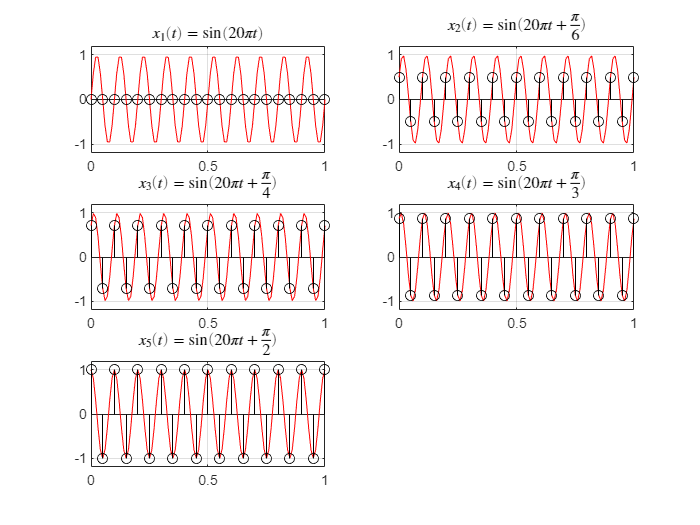

warning('off');
clear;
Ts = 0.05;
dt = 0.01;
t1 = 0:dt:1; 
t = 0:Ts:1;
x = [sin(20*pi*t); sin(20*pi*t + pi/6); sin(20*pi*t+ pi/4);
    sin(20*pi*t + pi/3); sin(20*pi*t + pi/2)];
x1 = [sin(20*pi*t1); sin(20*pi*t1 + pi/6); sin(20*pi*t1+ pi/4);
    sin(20*pi*t1 + pi/3); sin(20*pi*t1 + pi/2)];

figure();
subplot(3,2,1)
plot(t1,x1(1,:),'r');
title('$x_1(t) = \sin(20 \pi t)$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
hold on;
stem(t,x(1,:),'k');
subplot(3,2,2)
plot(t1,x1(2,:),'r');
title('$x_2(t) = \sin(20 \pi t + \frac{\pi}{6})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
hold on;
stem(t,x(2,:),'k');

subplot(3,2,3)
plot(t1,x1(3,:),'r');
title('$x_3(t) = \sin(20 \pi t + \frac{\pi}{4})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
hold on;
stem(t,x(3,:),'k');

subplot(3,2,4)
plot(t1,x1(4,:),'r');
title('$x_4(t) = \sin(20 \pi t + \frac{\pi}{3})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
hold on;
stem(t,x(4,:),'k');

subplot(3,2,5)
plot(t1,x1(5,:),'r');
title('$x_5(t) = \sin(20 \pi t + \frac{\pi}{2})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
hold on;
stem(t,x(5,:),'k');
hold off;

First order Hold Interpolation:

It is prior knowledge that if we have $x[n]$ the samples of a continuous signal $x_c(t)$ with sampling frequency $1/T_s$ then, 

we can reconstruct our signal with the help of First Order Hold (we sticked to the Nyquist rate):


$$y\underset{c}{} \;\left(t\right)=\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack \;\textrm{sinc}\left(\frac{t-{\textrm{nT}}_s }{T_s }\right)\;$$
  

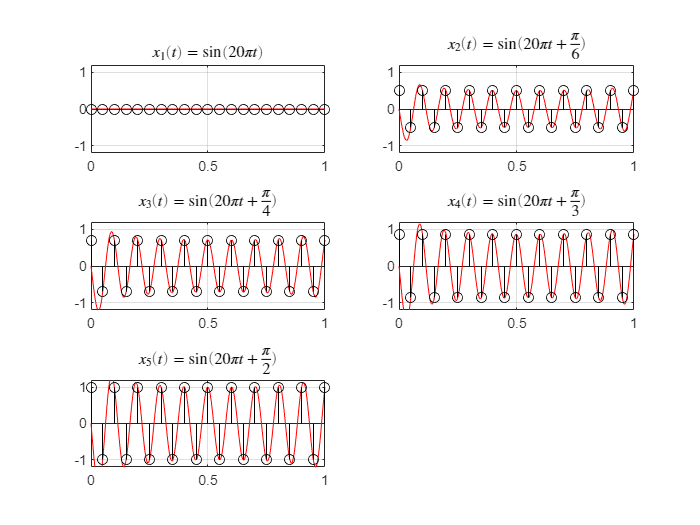

clear;
Ts = 0.05;
t = 0:Ts:1.;
delta = 0.001;
x = [sin(20*pi*t); sin(20*pi*t + pi/6); sin(20*pi*t+ pi/4);
    sin(20*pi*t + pi/3); sin(20*pi*t + pi/2)];
p = size(x(1,:));
t_recon = -.50:delta:1.5;
g = size(t_recon);
y_recon = zeros(5,g(2));

for i=1:5
    for n=1:p(2) 
        y_recon(i,:) = y_recon(i,:) - x(i,n) * sinc((t_recon-n*Ts)/Ts);
    end
end
figure();
subplot(3,2,1)
plot(t_recon,y_recon(1,:),'r');
title('$x_1(t) = \sin(20 \pi t)$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
xlim([0 1]);
hold on;
stem(t,x(1,:),'k');
subplot(3,2,2)
plot(t_recon,y_recon(2,:),'r');
title('$x_2(t) = \sin(20 \pi t + \frac{\pi}{6})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
xlim([0 1]);
hold on;
stem(t,x(2,:),'k');

subplot(3,2,3)
plot(t_recon,y_recon(3,:),'r');
title('$x_3(t) = \sin(20 \pi t + \frac{\pi}{4})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
xlim([0 1]);
hold on;
stem(t,x(3,:),'k');

subplot(3,2,4)
plot(t_recon,y_recon(4,:),'r');
title('$x_4(t) = \sin(20 \pi t + \frac{\pi}{3})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
xlim([0 1]);
hold on;
stem(t,x(4,:),'k');

subplot(3,2,5)
plot(t_recon,y_recon(5,:),'r');
title('$x_5(t) = \sin(20 \pi t + \frac{\pi}{2})$',interpreter='latex');
grid on 
ylim([-1.2 1.2]);
xlim([0 1]);
hold on;
stem(t,x(5,:),'k');
hold off;

As we can see the main signal is generated using FOH Interpolation, except for the case when we chose

 integer coefficients of $\pi$ as our data samples.

Cubic Spline Interpolation :

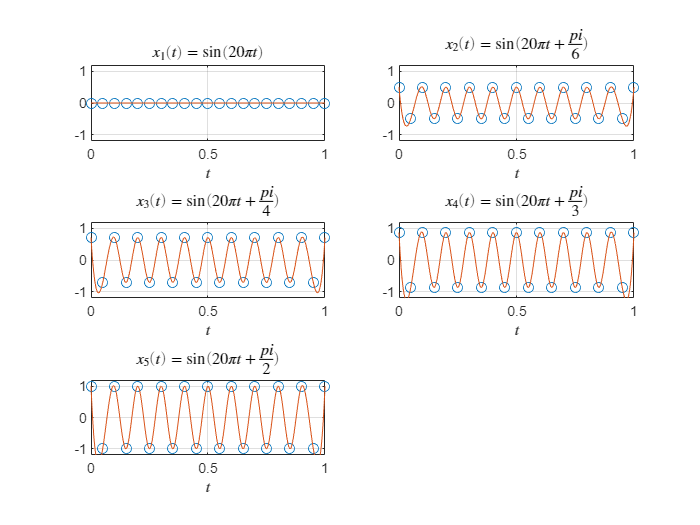

clear;
Ts = 0.05; 
t = 0:Ts:1; 
x = [sin(20*pi*t); sin(20*pi*t + pi/6); sin(20*pi*t+ pi/4);
    sin(20*pi*t + pi/3); sin(20*pi*t + pi/2)];
t_interp = 0:0.001:1;
h = size(t_interp);
x_interp = zeros(5,h(2));
x_interp(1,:) = spline(t, x(1,:), t_interp);
x_interp(2,:) = spline(t, x(2,:), t_interp);
x_interp(3,:) = spline(t, x(3,:), t_interp);
x_interp(4,:) = spline(t, x(4,:), t_interp);
x_interp(5,:) = spline(t, x(5,:), t_interp);

figure();
subplot(3,2,1);
plot(t, x(1,:), 'o', t_interp, x_interp(1,:), '-');
title('$x_1(t) = \sin(20 \pi t)$',interpreter='latex');
xlabel('$t$',Interpreter='latex');
grid on;
ylim([-1.2,1.2]);

subplot(3,2,2);
plot(t, x(2,:), 'o', t_interp, x_interp(2,:), '-');
title('$x_2(t) = \sin(20 \pi t + \frac{pi}{6})$',interpreter='latex');
xlabel('$t$',Interpreter='latex');
grid on;
ylim([-1.2,1.2]);

subplot(3,2,3);
plot(t, x(3,:), 'o', t_interp, x_interp(3,:), '-');
title('$x_3(t) = \sin(20 \pi t + \frac{pi}{4})$',interpreter='latex');
xlabel('$t$',Interpreter='latex');
grid on;
ylim([-1.2,1.2]);

subplot(3,2,4);
plot(t, x(4,:), 'o', t_interp, x_interp(4,:), '-');
title('$x_4(t) = \sin(20 \pi t + \frac{pi}{3})$',interpreter='latex');
xlabel('$t$',Interpreter='latex');
grid on;
ylim([-1.2,1.2]);

subplot(3,2,5);
plot(t, x(5,:), 'o', t_interp, x_interp(5,:), '-');
title('$x_5(t) = \sin(20 \pi t + \frac{pi}{2})$',interpreter='latex');
xlabel('$t$',Interpreter='latex');
grid on;
ylim([-1.2,1.2]);
hold off;

As we can see in the Cubic Spline method, unlike the FOH method, the reconstructed signal has resemblance to the intial signal. However, as we zoom in, we will notice that those signals mostly don't have the right amplitude with respect to sampled signal.

The reason is that Spline uses qubic polynomials and interpolates the signal. However, in FOH we are promised 

to reconstruct our signal

***Part 4:***

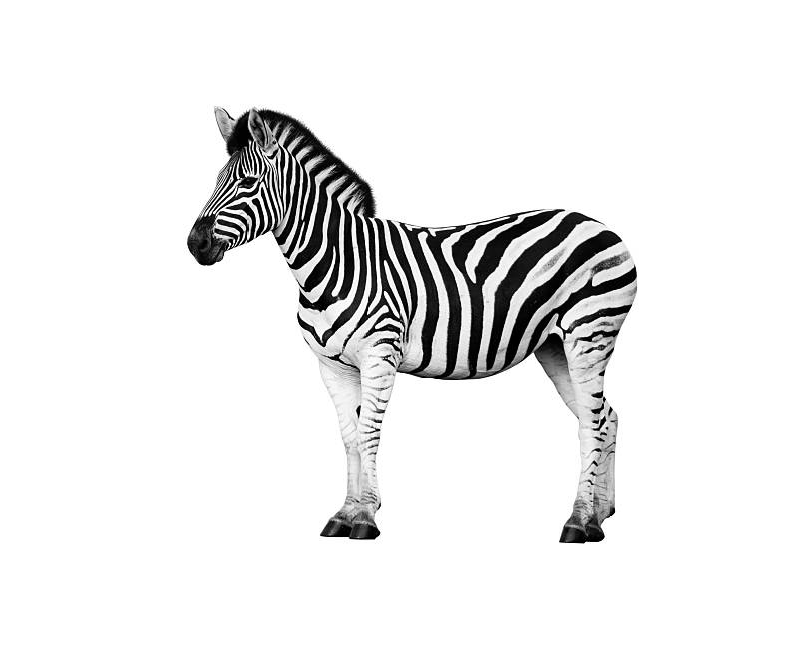

clear;
xx = imread("C:\Users\Parsa_The_Conqeuror\Desktop\dsphw1\Zebra.jpg");
gray_image = rgb2gray(xx);
figure();
imshow(gray_image);

***Nearest Neighbor:***

The nearest neighbor method selects the value of the nearest pixel from the original image to assign to the corresponding position in the upscaled image. 

For instance, if $(x,y)$ is the target position in the upscaled image, then the nearest neighbor value would be obtained from the closest pixel 

position $(x_{orig}, y_{orig})$in the original image using: $f(x,y) = I(x_{orig}, y_{orig})$.

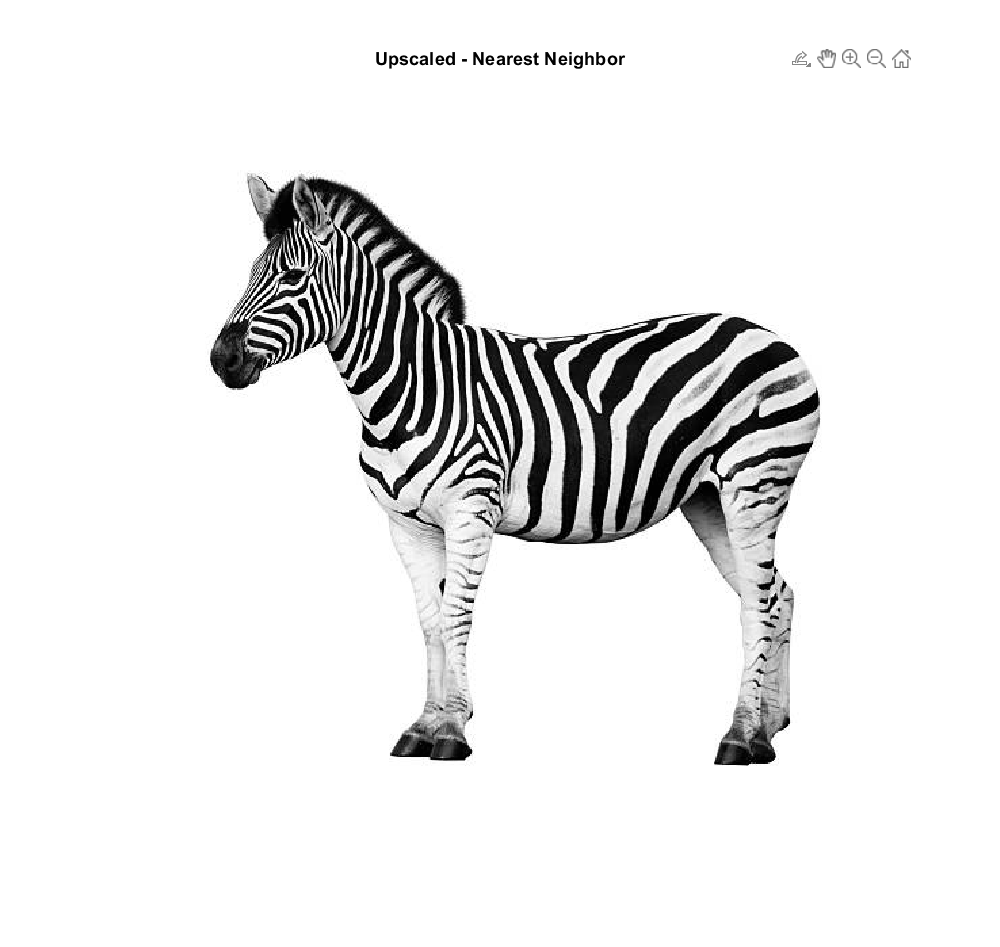

clear;
xx = imread("C:\Users\Parsa_The_Conqeuror\Desktop\dsphw1\Zebra.jpg");
gray_image = rgb2gray(xx);
target_size = [1668, 1836];
upscaled_nearest = zeros(target_size);
[orig_height, orig_width] = size(gray_image);
scaling_x = orig_height / 1668;
scaling_y = orig_width / 1836;
% Perform nearest neighbor interpolation manually
for i = 1:target_size(1)
    for j = 1:target_size(2)
        orig_x = round(i * scaling_x);
        orig_y = round(j * scaling_y);
        orig_x = min(max(orig_x, 1), orig_height);
        orig_y = min(max(orig_y, 1), orig_width);
        upscaled_nearest(i, j) = gray_image(orig_x, orig_y);
    end
end
figure();
imshow(upscaled_nearest,[]);
title('Upscaled - Nearest Neighbor');

size(upscaled_nearest)

ans =         1668        1836


As we can see, the size of the original image is now trippled.

***Bilinear Interpolation:***

For bilinear interpolation, the process involves calculating the weighted average of the intensity values of the four nearest pixels surrounding 

the target position $(x,y)$ in the original image. Let's assume that $Q_{11}, Q_{12}, Q_{21}, Q_{22}$  are the intensity values of the four neighboring pixels. 

Thus, the value at position $(x,y)$will be computed as:$f(x, y) = Q_{11} \cdot (1 - u) \cdot (1 - v) + Q_{12} \cdot u \cdot (1 - v) + Q_{21} \cdot (1 - u) \cdot v + Q_{22} \cdot u \cdot v$ 

where $u = x - \lfloor x \rfloor$ and also $v = y - \lfloor y \rfloor$.

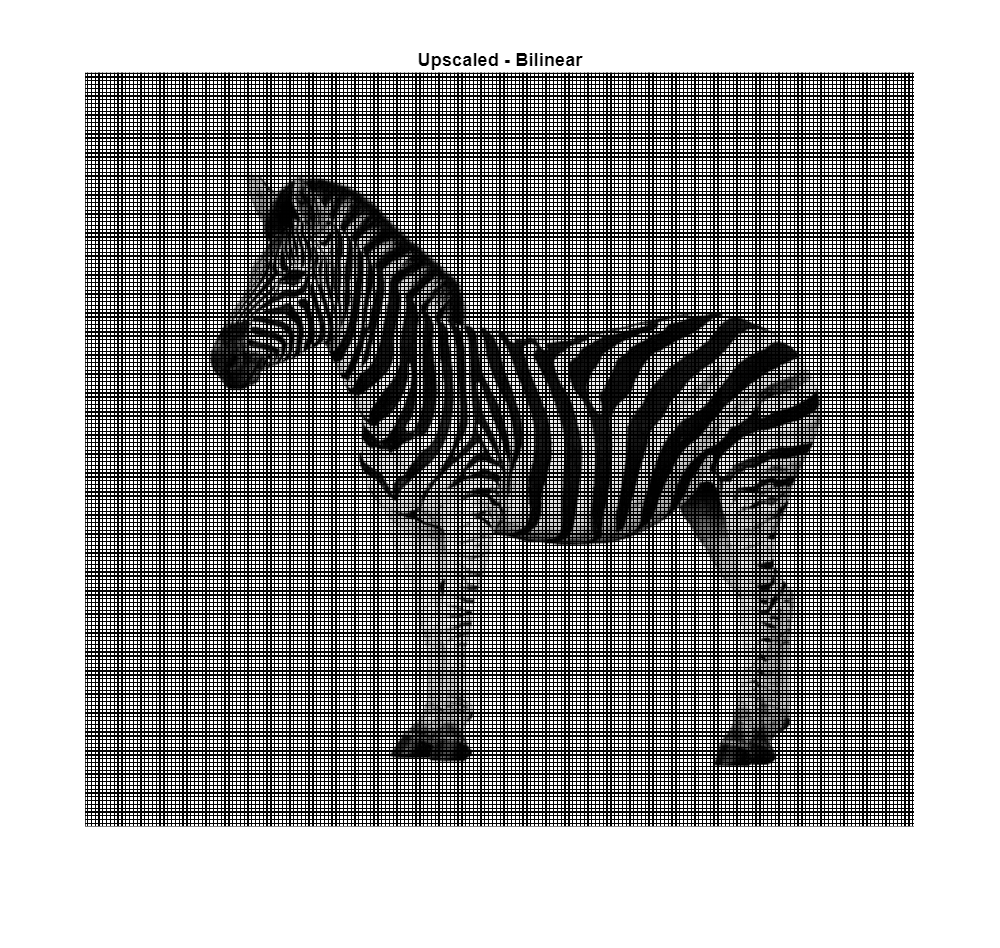

clear;
xx = imread("C:\Users\Parsa_The_Conqeuror\Desktop\dsphw1\Zebra.jpg");
gray_image = rgb2gray(xx);
target_size = [1668, 1836];
upscaled_nearest = zeros(target_size);
[orig_height, orig_width] = size(gray_image);
scaling_x = orig_height / 1668;
scaling_y = orig_width / 1836;

% Perform bilinear interpolation manually
for i = 1:1668
    for j = 1:1836
        orig_x = i * scaling_x;
        orig_y = j * scaling_y;
        x1 = floor(orig_x);
        x2 = ceil(orig_x);
        y1 = floor(orig_y);
        y2 = ceil(orig_y);
        x1 = min(max(x1, 1), orig_height);
        x2 = min(max(x2, 1), orig_height);
        y1 = min(max(y1, 1), orig_width);
        y2 = min(max(y2, 1), orig_width);
        f = gray_image(x1, y1);
        g = gray_image(x1, y2);
        h = gray_image(x2, y1);
        k = gray_image(x2, y2);
        upscaled_bilinear(i, j) = ((x2 - orig_x) * (y2 - orig_y) * f + (orig_x - x1) * (y2 - orig_y) * h + ...
                                   (x2 - orig_x) * (orig_y - y1) * g + (orig_x - x1) * (orig_y - y1) * k);
    end
end

imshow(upscaled_bilinear);
title('Upscaled - Bilinear');

***Part 5:***

In Quantization from a continuous domain to a Quantized mechnical range, we assume that a white noise will be added to our signal,

 which ironically will turn out to be wrong in reality. With parameters $N = B+1 = 4$ bits, $2A=2 = 2X_m
$ mechanical range, our signal $x(t) = A sin(2\pi f_0 t)$,

and sampling frequency $f_s = 10kHz$, $\Delta = \frac{2X_m}{2^N} = \frac{1}{8}$ , we will quantize the signal $x(t)$. In quantized domain, our range will be $-2^{N-1}, ..., 0 , 1, ... 2^{N-1}-1$ .

In order to get the index of quantization we will find that using $k[n] =  A \frac{ \lfloor \frac{x(nT_s)}{A}* (2^{N-1}-1) \rfloor}{2^{N-1}-1}$ . 

First we will plot $x_q (t)$and $x(t)$.

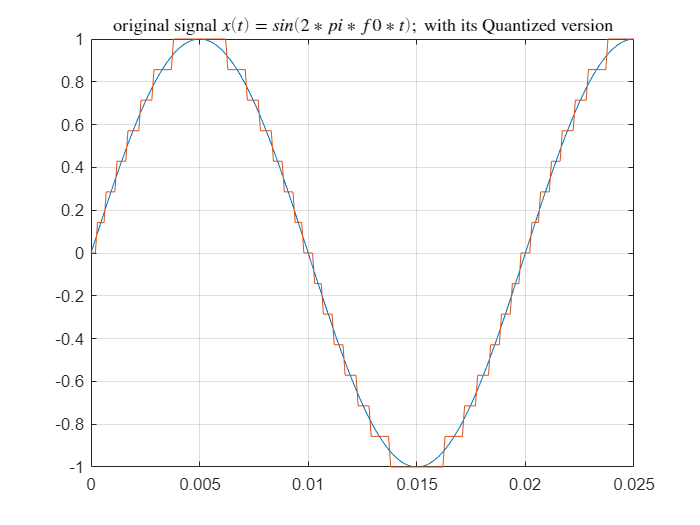

fs = 10000;   
Ts = 1/fs;
f0 = 50;      
A = 1;       
t = 0:1/fs:0.025; 
N = 4;       
x = A * sin(2*pi*f0*t);
x_quantized = round((2^(N-1)-1) * x/A) * A / (2^(N-1)-1);
figure();
plot(t, x);
title(' original signal $x(t) =sin(2*pi*f0*t);$ with its Quantized version',Interpreter='latex');
hold on
plot(t, x_quantized);
grid on;

We are asked to get FFT of $x_q (t)$ and plot it in frequency domain:

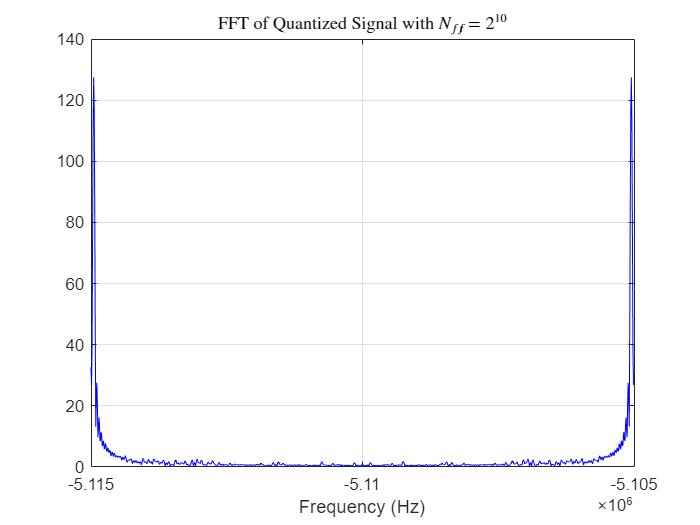

N_fft = 2^10;
X_fft = fft(x_quantized, N_fft);
%freqs = linspace(-fs, fs, N_fft);
freqs = fs/N_fft * (0:1:N_fft -1) - fs*(N_fft -1)/2;
figure();
plot(freqs, abs(X_fft),'blue');
title('FFT of Quantized Signal with $N_{fft} = 2^{10}$',Interpreter='latex');
xlabel('Frequency (Hz)');
grid on;

Now , we define the error to be $e(t) = x(t) - x_q (t)$

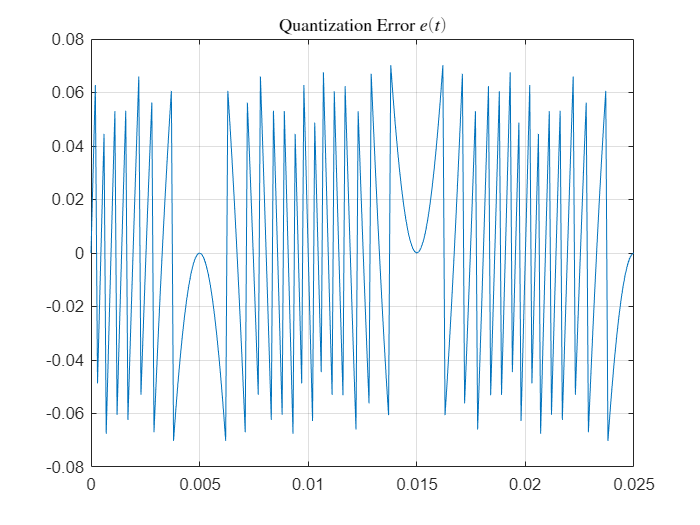

e = x - x_quantized;
figure();
plot(t, e);
grid on;
title('Quantization Error $e(t)$',interpreter='latex');

Here, the FFT of $e(t)$ is depicted:

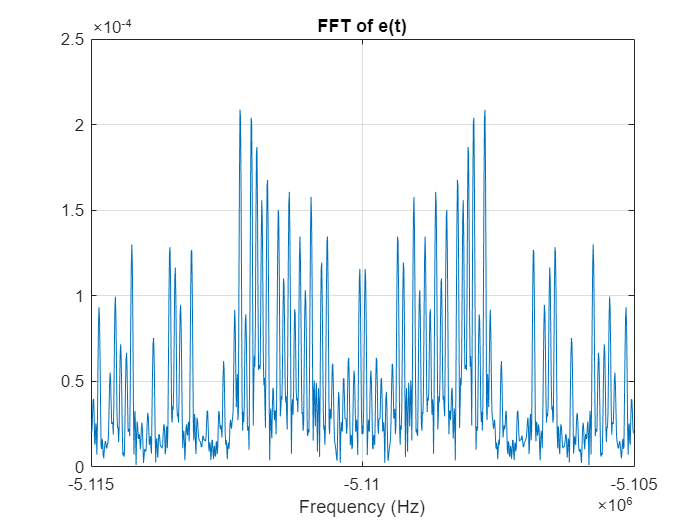

%e_fft = fft(e, N_fft);
e_fft = fft(e,N_fft)/fs;
plot(freqs, abs(fftshift(e_fft)));
xlabel('Frequency (Hz)');
title('FFT of e(t)');
grid on;

However, as we mentioned earlier, we expected the FFT of quantization error to be uniform among all frequencied as white Gaussian noise.

As you can see this is not what happened here which shows that this assumption was not true that we can rewrite $x(t)$ as $x[n] = x_q[n] + e[n]$ 

where $e[n]$ is a WGN.

The peaks ocurre at $f = +- 0.6 Hz$ which is in synch with $f_{tone} =  \frac{4 A}{\Delta N_{fft} } f_s =\frac{32}{210} 10^4 = 1523Hz$.  

(2*pi/N_fft)^(-1) * 0.6

ans = 97.7848

Now we will estimate the period using FFT of quantization error:

signal = e;
M = length(signal); % Number of samples
Y = fft(signal);
P2 = abs(Y/M);
P1 = P2(1:M/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(M/2))/M;
% Find the dominant frequency component
[~, index] = max(P1);
dominant_frequency = f(index)

dominant_frequency = 1.9522e+03

estimated_period = 1 / dominant_frequency % Estimated period

estimated_period = 5.1224e-04

and this is close to the peak of the fft.

Eventually, we will repeat what we have done for $N=6,8,10,12$ bits:

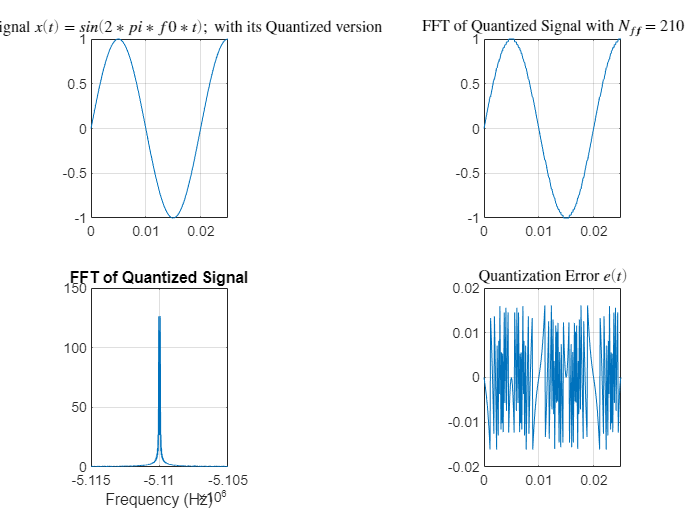

% N = 6
% defining the parameters
fs = 10000;   
Ts = 1/fs;
f0 = 50;      
A = 1;       
t = 0:1/fs:0.025; 
N = 6;       
x = A * sin(2*pi*f0*t);
x_quantized = round((2^(N-1)-1) * x/A) * A / (2^(N-1)-1);
N_fft = 2^10;
X_fft = fft(x_quantized, N_fft);
e = x - x_quantized;

% plotting
figure();
subplot(2,3,1);
plot(t, x);
title(' original signal $x(t) =sin(2*pi*f0*t);$ with its Quantized version',Interpreter='latex');
grid on;

subplot(2,3,3);
plot(t, x_quantized);
title('FFT of Quantized Signal with $N_{fft} = 210$',Interpreter='latex');
grid on;

subplot(2,3,4);
%freqs = linspace(-fs, fs, N_fft);
freqs = fs/N_fft * (0:1:N_fft -1) - fs*(N_fft -1)/2;
% for the sake of symmetry.
plot(freqs, abs(fftshift(X_fft)));
title('FFT of Quantized Signal');
xlabel('Frequency (Hz)');
grid on;

subplot(2,3,6);
plot(t, e);
grid on;
title('Quantization Error $e(t)$',interpreter='latex');

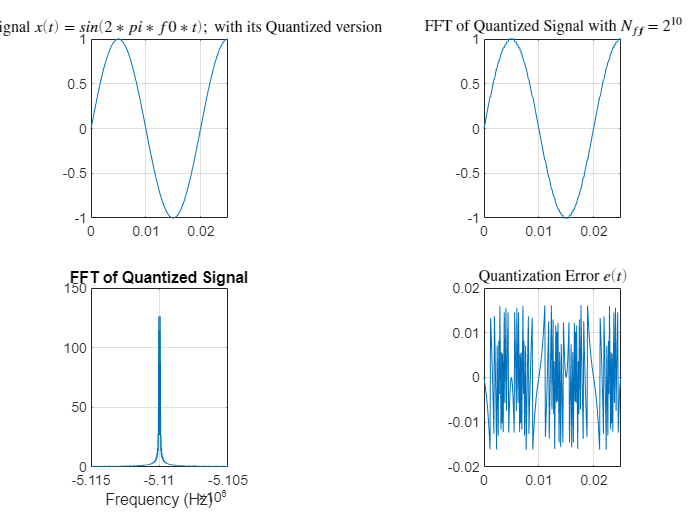

% N = 8
% defining the parameters
fs = 10000;   
Ts = 1/fs;
f0 = 50;      
A = 1;       
t = 0:1/fs:0.025; 
N = 6;       
x = A * sin(2*pi*f0*t);
x_quantized = round((2^(N-1)-1) * x/A) * A / (2^(N-1)-1);
N_fft = 2^10;
X_fft = fft(x_quantized, N_fft);
e = x - x_quantized;

% plotting
figure();
subplot(2,3,1);
plot(t, x);
title(' original signal $x(t) =sin(2*pi*f0*t);$ with its Quantized version',Interpreter='latex');
grid on;

subplot(2,3,3);
plot(t, x_quantized);
title('FFT of Quantized Signal with $N_{fft} = 2^{10}$',Interpreter='latex');
grid on;

subplot(2,3,4);
%freqs = linspace(-fs, fs, N_fft);
freqs = fs/N_fft * (0:1:N_fft -1) - fs*(N_fft -1)/2;
% for the sake of symmetry.
plot(freqs, abs(fftshift(X_fft)));
title('FFT of Quantized Signal');
xlabel('Frequency (Hz)');
grid on;

subplot(2,3,6);
plot(t, e);
grid on;
title('Quantization Error $e(t)$',interpreter='latex');

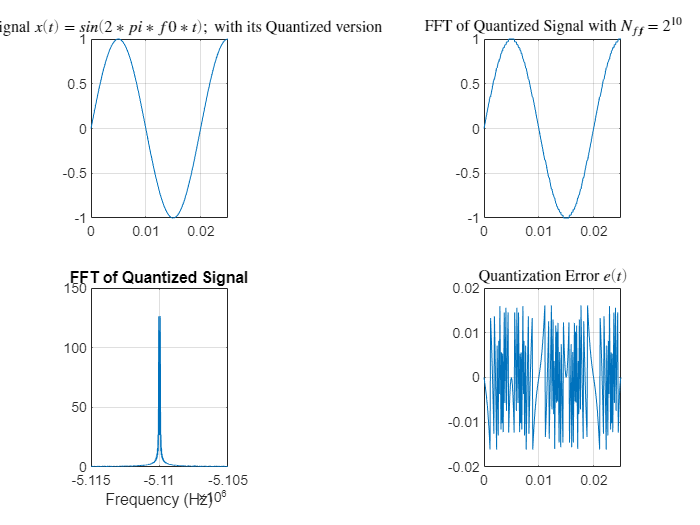

% N = 10
% defining the parameters
fs = 10000;   
Ts = 1/fs;
f0 = 50;      
A = 1;       
t = 0:1/fs:0.025; 
N = 6;       
x = A * sin(2*pi*f0*t);
x_quantized = round((2^(N-1)-1) * x/A) * A / (2^(N-1)-1);
N_fft = 2^10;
X_fft = fft(x_quantized, N_fft);
e = x - x_quantized;

% plotting
figure();
subplot(2,3,1);
plot(t, x);
title(' original signal $x(t) =sin(2*pi*f0*t);$ with its Quantized version',Interpreter='latex');
grid on;

subplot(2,3,3);
plot(t, x_quantized);
title('FFT of Quantized Signal with $N_{fft} = 2^{10}$',Interpreter='latex');
grid on;

subplot(2,3,4);
%freqs = linspace(-fs, fs, N_fft);
freqs = fs/N_fft * (0:1:N_fft -1) - fs*(N_fft -1)/2;
% for the sake of symmetry.
plot(freqs, abs(fftshift(X_fft)));
title('FFT of Quantized Signal');
xlabel('Frequency (Hz)');
grid on;

subplot(2,3,6);
plot(t, e);
grid on;
title('Quantization Error $e(t)$',interpreter='latex');

% N = 12
% defining the parameters
fs = 10000;   
Ts = 1/fs;
f0 = 50;      
A = 1;       
t = 0:1/fs:0.025; 
N = 6;       
x = A * sin(2*pi*f0*t);
x_quantized = round((2^(N-1)-1) * x/A) * A / (2^(N-1)-1);
N_fft = 2^10;
X_fft = fft(x_quantized, N_fft);
e = x - x_quantized;

% plotting
figure();
subplot(2,3,1);
plot(t, x);
title(' original signal $x(t) =sin(2*pi*f0*t);$ with its Quantized version',Interpreter='latex');
grid on;

subplot(2,3,3);
plot(t, x_quantized);
title('FFT of Quantized Signal with $N_{fft} = 2^{10}$',Interpreter='latex');
grid on;

subplot(2,3,4);
%freqs = linspace(-fs, fs, N_fft);
freqs = fs/N_fft * (0:1:N_fft -1) - fs*(N_fft -1)/2;
% for the sake of symmetry.
plot(freqs, abs(fftshift(X_fft)));
title('FFT of Quantized Signal');
xlabel('Frequency (Hz)');
grid on;

subplot(2,3,6);
plot(t, e);
grid on;
title('Quantization Error $e(t)$',interpreter='latex');

function [h,c] = dcolor(varargin)
% attention: we have used this function earlier in part 1:
% and we got assistance from this url:
% https://www.mathworks.com/matlabcentral/fileexchange/29028-dcolor#:~:text=DCOLOR%20uses%20a%20coloring%20function,handle%20as%20the%20source%20data.
cFun = 1;
gridFlag = 0;
minX = -1;
maxX = 1;
minY = -1;
maxY = 1;
nPts = 512;
surfaceFlag = 0;
% If the first input is an axes handle, use it
if (isscalar(varargin{1}) && ...
        ishghandle(varargin{1}) && ...
        strcmp(get(varargin{1},'Type'),'axes'))
    hAx = newplot(varargin{1});
    varargin(1) = [];
else
    hAx = newplot;
end
% Look for the strings 'CFun' and 'grid' in the inputs 
charIdx = cellfun(@ischar,varargin);
for k = find(charIdx)
    switch lower(varargin{k})
        case 'cfun'
            cFun = varargin{k+1};
        case 'grid'
            gridFlag = 1;
    end
end
varargin(find(charIdx,1):end) = [];
% Get the x, y and w data
if isempty(varargin)
    % Plot a color function over (-1 -1i) to (1 + 1i)
    x = linspace(-1,1,nPts);
    y = x;
    [X Y] = meshgrid(x);
    w = X + 1i*Y;
elseif length(varargin) == 1 
    if isnumeric(varargin{1}) && all(size(varargin{1}) == [1 2])
        % Plot a color function over the specified domain
        minX = real(varargin{1}(1));
        maxX = real(varargin{1}(2));
        minY = imag(varargin{1}(1));
        maxY = imag(varargin{1}(2));
        x = linspace(minX,maxX,nPts);
        y = linspace(minY,maxY,nPts);
        [X,Y] = meshgrid(x,y);
        w = X + 1i*Y;
    elseif isnumeric(varargin{1})
        % Plot w with integer-spaced domain of size(w)
        w = varargin{1};
        minX = 1;
        maxX = size(w,2);
        minY = 1;
        maxY = size(w,1);
        x = minX:maxX;
        y = minY:maxY;
    else
        % Plot w = @fz(z) over (-1 -1i) to (1 + 1i)
        x = linspace(-1,1,nPts);
        y = x;
        [X,Y] = meshgrid(x);
        w = feval(varargin{1},(X+1i*Y));
    end
elseif length(varargin) == 2
    % Plot w = @fz(z) over the specified domain
    minX = real(varargin{1}(1));
    maxX = real(varargin{1}(2));
    minY = imag(varargin{1}(1));
    maxY = imag(varargin{1}(2));
    x = linspace(minX,maxX,nPts);
    y = linspace(minY,maxY,nPts);
    [X,Y] = meshgrid(x,y);
    w = feval(varargin{2},(X+1i*Y));
elseif length(varargin) == 3
    % Domain is [min(x)+i*min(y), max(x)+i*max(y)], with grid points at x
    % and y.  x and y can be vector or matrix (meshgrid-style).
    if min(size(varargin{1})) == 1;
        x = varargin{1};
        y = varargin{2};
        minX = x(1);
        maxX = x(end);
        minY = y(1);
        maxY = y(end);
        % Check for non-uniform grid
        if max(diff(x))-min(diff(x)) > ...
                4*max(eps(minX),eps(maxX)) || ...
           max(diff(y))-min(diff(y)) > ...
                4*max(eps(minY),eps(maxY))
            % Non-uniform grid, use surface instead of image
            surfaceFlag = 1;
        end
        [X,Y] = meshgrid(x,y);
    else
        % If a matrix of gridpoints was given, use surface instead of image
        X = varargin{1};
        Y = varargin{2};
        surfaceFlag = 1;
    end
    if isnumeric(varargin{3})
        % w data was supplied as input
        w = varargin{3};
    else
        % Calculate w=@fz(z) using @fz supplied as input
        w = feval(varargin{3},(X+1i*Y));
    end
else
    msgid = [mfilename ':InvalidInputs'];
    msgtext = ['Invalid input.  Type ''help ' mfilename ...
               ''' for correct syntax'];
    error(msgid,msgtext)
end
if surfaceFlag == 0
    clear X Y
end
%% Compute the color data and make the plot
% Create a grid if necessary
if gridFlag == 1
    % Compute contour levels
    levels = DColorGrid(w);
    % Find and plot contours for real(w)
    if surfaceFlag == 1
        C = contours(X,Y,real(w),levels{1});
    else
        C = contourc(x,y,real(w),levels{1});
    end
    hCReal = hggroup('Parent',hAx);
    pos = 1;
    while pos < size(C,2)
        linepts = C(2,pos);
        line('XData',C(1,(pos+1):(pos+linepts)),...
            'YData',C(2,(pos+1):(pos+linepts)),...
            'Parent',hCReal,...
            'LineStyle','-',...
            'Color',[0 0 0],...
            'LineWidth',0.5)
        pos = pos+linepts+1;
    end
    % Find and plot contours for imag(w)
    if surfaceFlag == 1
        C = contours(X,Y,imag(w),levels{2});
    else
        C = contourc(x,y,imag(w),levels{2});
    end
    hCImag = hggroup('Parent',hAx);
    pos = 1;
    while pos < size(C,2)
        linepts = C(2,pos);
        line('XData',C(1,(pos+1):(pos+linepts)),...
            'YData',C(2,(pos+1):(pos+linepts)),...
            'Parent',hCImag,...
            'LineStyle',':',...
            'Color',[0 0 0],...
            'LineWidth',0.5)
        pos = pos+linepts+1;
    end
    % Save handles so we can make sure grid is displayed on top
    hC = [hCImag; hCReal];
end
% Calculate color data using a coloring function
if isa(cFun,'function_handle')
    % Call the user-supplied function handle
    CData = feval(cFun,w);
else
    % Use one of the built-in coloring functions
    CData = DColorColorFunctions(w,cFun);
end
clear w
if surfaceFlag == 0
    YDir = get(hAx,'YDir');
    hPlot = image('XData',[minX maxX],...
                  'YData',[minY maxY],...
                  'CData',CData,...
                  'Parent',hAx);
    set(hAx,'YDir',YDir)
else
    hPlot = surface(X,Y,zeros(size(X)),...
                    'CData',CData,...
                    'EdgeColor','none',...
                    'FaceColor','flat',...
                    'Parent',hAx);
end
if gridFlag == 1
    % Make sure grid is displayed on top of image
    hh = get(hAx,'Children');
    idxC = (hh==hC(2));
    idxI = (hh==hPlot);
    hh(idxC) = hPlot;
    hh(idxI) = hC(2);
    set(hAx,'Children',hh)
end
if strcmp(get(hAx,'XLimMode'),'auto') && strcmp(get(hAx,'YLimMode'),'auto')
    axis(hAx,'tight')
end
    
% If asked for, return the handle to the image/surface
if nargout ~= 0
    h = hPlot;
end
% If asked for, return the image data
if nargout == 2
    c = CData;
end
end % End of function dcolor
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function x = iplog10(x)
% In-place implementation of log10 for reduced memory use
x = log2(x);
x = x/6.64385618977472436 + x/6.64385618977472525;
end % End of function iplog10
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function  CData = DColorColorFunctions(w,cFunction)
%Domain coloring functions for plotting complex data
%
% Transforms the complex data in the MxN matrix W into an MxNx3 array of
% RGB values using the algorithm selected by cFunction.  Subfunction used
% by dcolor.m.
%
%% Calculate the color data matrix in HSV space
% Get page size for ugly indexing operations
ps = numel(w); 
if cFunction == 1
    CData = cat(3,angle(w),abs(w),abs(w));
    % Shift H so that a 0 degree angle has an HSV hue of 0 (red)
    CData(CData(:,:,1)<0) = CData(CData(:,:,1)<0)+2*pi;
    % Normalize H to [0,1]
    CData(:,:,1) = CData(:,:,1)/(2*pi);
    % Compute saturation and brightness from modulus
    CData(:,:,2) = 1./(1+0.33*iplog10(CData(:,:,2)./10+1));
    CData(:,:,3) = 1 - 1./(1.1+25*iplog10(2*CData(:,:,3)+1));
    
elseif cFunction == 2
    CData = cat(3,angle(w),iplog10(abs(w)),zeros(size(w)));
    % Shift H so that a 0 degree angle has an HSV hue of 0 (red)
    CData(CData(:,:,1)<0) = CData(CData(:,:,1)<0)+2*pi;
    % Normalize H to [0,1]
    CData(:,:,1) = CData(:,:,1)/(2*pi);
    % Compute saturation and brightness from normalized modulus. Start with
    % log10(modulus).  Compute 2 and 98 percentiles, then compress data
    % outside of this range and normalize to [0,1].  This is then fed into
    % the S and V calculations.
    CData(ps+find(isinf(CData(:,:,2)))) = NaN;
    CData(:,:,3) = reshape(sort(CData((ps+1):(2*ps))),size(CData(:,:,2)));
    lastdat = 2*ps+find(isnan(CData(:,:,3)),1)-1;
    lastdat(isempty(lastdat)) = 3*ps;
    q = [0 100*(0.5:(lastdat-2*ps+1-0.5))./(lastdat-2*ps+1) 100]';
    x = [CData(2*ps+1); CData((2*ps+1):lastdat)'; CData(lastdat)];
    % 2 calls to interp1q with scalar xi are faster than 1 call with vector
    y(2) = interp1q(q,x,98);
    y(1) = interp1q(q,x,2);
    idx = ps+find(CData(:,:,2)<y(1));
    CData(idx) = y(1)+2/pi*(atan(CData(idx)-max(CData(idx))-.5)-atan(-.5));
    idx = ps+find(CData(:,:,2)>y(2));
    CData(idx) = y(2)+2/pi*(atan(CData(idx)-min(CData(idx))+.5)-atan(.5));
    CData(:,:,2) = (CData(:,:,2)-min(min(CData(:,:,2))))/...
                   (max(max(CData(:,:,2)))-min(min(CData(:,:,2))));
    % Calculate S and V using atan(), then normalize to [0.1,1)
    CData(:,:,3) = CData(:,:,2);
    CData(:,:,2) = 1 - atan(CData(:,:,2).^3 - 1);
    CData(:,:,2) = 0.89999*(CData(:,:,2)-min(min(CData(:,:,2))))/...
                   (max(max(CData(:,:,2)))-min(min(CData(:,:,2)))) + 0.1;
    CData(:,:,3) = atan((CData(:,:,3)+1).^3);
    CData(:,:,3) = 0.79999*(CData(:,:,3)-min(min(CData(:,:,3))))/...
                   (max(max(CData(:,:,3)))-min(min(CData(:,:,3)))) + 0.2;
    
elseif cFunction == 3
    CData = cat(3,angle(w),abs(w),abs(w));
    % Shift H so that a 0 degree angle has an HSV hue of 0 (red)
    CData(CData(:,:,1)<0) = CData(CData(:,:,1)<0)+2*pi;
    % Normalize H to [0,1]
    CData(:,:,1) = CData(:,:,1)/(2*pi);
    % Make dark:normal:light bands for every decade of modulus
    CData(ps+find(isinf(CData(:,:,2)))) = NaN;
    CData(:,:,2) = iplog10(CData(:,:,2)) - floor(iplog10(CData(:,:,2)));
    CData(:,:,2) = 10.^(CData(:,:,2));
    CData(:,:,3) = CData(:,:,2);
    CData(:,:,2) = atan(CData(:,:,2).^5);
    CData(:,:,2) = 0.59999*(CData(:,:,2)-min(min(CData(:,:,2))))/...
                   (max(max(CData(:,:,2)))-min(min(CData(:,:,2)))) + 0.4;
    CData(:,:,3) = 1-atan(((CData(:,:,3)/10).^10-1));
    CData(:,:,3) = 0.59999*(CData(:,:,3)-min(min(CData(:,:,3))))/...
                   (max(max(CData(:,:,3)))-min(min(CData(:,:,3)))) + 0.4;
    
elseif cFunction == 4
    CData = cat(3,abs(w),angle(w),angle(w));
    % Compute hue from normalized modulus
    CData(isinf(CData(:,:,1))) = NaN;
    CData(:,:,1) = 0.84999*(CData(:,:,1)-min(min(CData(:,:,1))))/...
                   (max(max(CData(:,:,1)))-min(min(CData(:,:,1))))+0.00001;
    % Use angle: [-pi,pi)
    CData(:,:,2) = (CData(:,:,2) + pi)/(2*pi);
    CData(:,:,3) = CData(:,:,2);
    CData(:,:,2) = 1-1./(1.01+19*iplog10(-CData(:,:,2)+2));
    CData(:,:,3) = 1-1./(1.01+19*iplog10(CData(:,:,3)+1));
    
elseif cFunction == 5
    CData = cat(3,abs(w),angle(w),angle(w));
    % Compute hue from normalized modulus
    CData(isinf(CData(:,:,1))) = NaN;
    CData(:,:,1) = 0.84999*(CData(:,:,1)-min(min(CData(:,:,1))))/...
                   (max(max(CData(:,:,1)))-min(min(CData(:,:,1))))+0.00001;
    % Use angle: [0,2*pi) 
    CData(ps+find(CData(:,:,2)<0)) = CData(ps+find(CData(:,:,2)<0))+2*pi;
    CData(:,:,2) = CData(:,:,2)/(2*pi);
    CData(:,:,3) = CData(:,:,2);
    CData(:,:,2) = 1-1./(1.0+39*iplog10(-CData(:,:,2)+2));
    CData(:,:,3) = 1-1./(1.0+39*iplog10(CData(:,:,3)+1));
               
elseif cFunction == 6
    CData = cat(3,angle(w),ones(size(w)),ones(size(w)));
    % Saturation and brightness are fixed at 1
    % Shift H so that a 0 degree angle has an HSV hue of 0 (red)
    CData(CData(:,:,1)<0) = CData(CData(:,:,1)<0)+2*pi;
    % Normalize H to [0,1]
    CData(:,:,1) = CData(:,:,1)/(2*pi);
               
elseif cFunction == 7             
    CData = cat(3,abs(w),ones(size(w)),ones(size(w)));
    % Saturation and brightness are fixed at 1
    % Compute hue from normalized modulus
    CData(:,:,1) = iplog10(CData(:,:,1)+1);
    CData(isinf(CData(:,:,1))) = NaN;
    CData(:,:,1) = 0.84999*(CData(:,:,1)-min(min(CData(:,:,1))))/...
                   (max(max(CData(:,:,1)))-min(min(CData(:,:,1))))+0.00001;
else
    % For invalid cFunction, call ourselves recursively with cFunction = 1
    CData = DColorColorFunctions(w,1);
    return
end
%%
% Now convert the HSV values to RGB.  Do it this way (with ugly code)
% because it is much more memory efficient than calling hsv2rgb().
%
% The transform is:
% Inputs:
% h: [0,6)
% s and v: [0,1]
% Intermediate values:
% f =  h-floor(h),   floor(h) odd
%      1-h+floor(h), floor(h) even
% m = v*(1-s)
% n = v*(1-s*f)
% Outputs (all [0,1]):
% (r,g,b) = (v,n,m),   0<=h<1
%           (n,v,m),   1<=h<2
%           (m,v,n),   2<=h<3
%           (m,n,v),   3<=h<4
%           (n,m,v),   4<=h<5
%           (v,m,n),   5<=h<6
% Renormalize hue from [0,1] to [0,6)
CData(:,:,1) = CData(:,:,1)*6;
CData(CData(:,:,1)==6) = 0;
% Group hue values into 6 bins
hp = uint8(floor(CData(:,:,1))); 
% Compute intermediate values: f, n+v, m-v
CData(:,:,1) = CData(:,:,1)-double(hp); % f=h-floor(h)
CData(:,:,1) = CData(:,:,3).*(1 - CData(:,:,2).*(1 - double(mod(hp,2))+...
           CData(:,:,1).*(-1).^double(1+mod(hp,2)))) + CData(:,:,3); %n+v  
CData(:,:,2) = -CData(:,:,3).*CData(:,:,2); %m-v
% CData now has (n+v,m-v,v).  The rest of the code is to shift these values
% around to get permutations of (v,n,m), depending on the hue.
% 0 <= h < 1 : (n+v,m-v,v)->(v,n,m)
idx = find(hp==0);
CData(idx+2*ps) =             +CData(idx+ps) +CData(idx+2*ps); %(n+v,m-v,m)
CData(idx+ps)   = +CData(idx) +CData(idx+ps) -CData(idx+2*ps); %(n+v,n,m)
CData(idx)      = +CData(idx) -CData(idx+ps)                 ; %(v,n,m)
% 1 <= h < 2 :(n+v,m-v,v)->(n,v,m)
idx = find(hp==1);
CData(idx)      = +CData(idx)                -CData(idx+2*ps); %(n,m-v,v)
CData(idx+2*ps) =             +CData(idx+ps) +CData(idx+2*ps); %(n,m-v,m)
CData(idx+ps)   =             -CData(idx+ps) +CData(idx+2*ps); %(n,v,m)
% 2 <= h < 3 :(n+v,m-v,v))->(m,v,n)
idx = find(hp==2);
CData(idx+2*ps) = +CData(idx)                -CData(idx+2*ps); %(n+v,m-v,n)
CData(idx)      = +CData(idx) +CData(idx+ps) -CData(idx+2*ps); %(m,m-v,n)
CData(idx+ps)   = +CData(idx) -CData(idx+ps)                 ; %(m,v,n)
% 3 <= h < 4 :(n+v,m-v,v)->(m,n,v)
idx = find(hp==3);
CData(idx+ps)   = +CData(idx) +CData(idx+ps)                 ; %(n+v,m+n,v)
CData(idx)      = -CData(idx) +CData(idx+ps) +CData(idx+2*ps); %(m,m+n,v)
CData(idx+ps)   = -CData(idx) +CData(idx+ps)                 ; %(m,n,v)
% 4 <= h < 5 :(n+v,m-v,v)->(n,m,v)
idx = find(hp==4);
CData(idx)      = +CData(idx)                -CData(idx+2*ps); %(n,m-v,v)
CData(idx+ps)   =             +CData(idx+ps) +CData(idx+2*ps); %(n,m,v)
% 5 <= h < 6 :(n+v,m-v,v)->(v,m,n)
idx = find(hp==5);
CData(idx+2*ps) = +CData(idx)                -CData(idx+2*ps); %(n+v,m-v,n)
CData(idx)      = +CData(idx)                -CData(idx+2*ps); %(v,m-v,n)
CData(idx+ps)   = +CData(idx) +CData(idx+ps)                 ; %(v,m,n)
end % End of function DColorColorFunctions 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function gridLevels = DColorGrid(w)
% Get contour levels for a grid overlay on a DCOLOR plot.
%
% The grid overlay on a DCOLOR plot is created by calling CONTOUR() twice
% with the real and imaginary parts of W.  Because DCOLOR plots often have
% a large dynamic range, DCOLORGRID tries to calculate log-scale contour
% levels (for both positive and negative data) which are then supplied to
% the CONTOUR routine in place of the default values.  It doesn't always
% work out perfectly, but usually looks better than the default output of
% CONTOUR.
gridLevels = cell(1,2);
% Loop twice, once for real(w), once for imag(w)
for m = 1:2
    % Zero-crossing flag
    zeroFlag = 0;
    
    if m == 1
        minW = min(real(w(isfinite(real(w(:))))));
        maxW = max(real(w(isfinite(real(w(:))))));
        [modeWP fP] = mode(floor(iplog10(real(w(real(w(:))>0)))));
        fZ = length(find(real(w(:))==0));
        [modeWN fN] = mode(floor(iplog10(-real(w(real(w(:))<0)))));
    else
        minW = min(imag(w(isfinite(imag(w(:))))));
        maxW = max(imag(w(isfinite(imag(w(:))))));
        [modeWP fP] = mode(floor(iplog10(imag(w(imag(w(:))>0)))));
        fZ = length(find(imag(w(:))==0));
        [modeWN fN] = mode(floor(iplog10(-imag(w(imag(w(:))<0)))));
    end
    modeWDec = [modeWP 0 modeWN];
    f = [fP fZ fN];
    modeSgn = [1 0 -1];
    if length(find(f==max(f))) == 1
        modeWDec = modeWDec(find(f==max(f),1));
        modeSgn = modeSgn(find(f==max(f),1));
    else
        modeWDec = 0;
        modeSgn = 1;
    end
   
    if maxW - minW < 100
        % If the range is small, try to get 'nice' contour levels
        normRange = (maxW-minW)/10^floor(iplog10(maxW-minW));
        if normRange  < 1.2
            stepVal = (maxW-minW)/(normRange*10);
        elseif normRange < 2.4
            stepVal = (maxW-minW)/(normRange*5);
        else
            stepVal = (maxW-minW)/(normRange*4);
        end
        
        if minW < 0 && maxW > 0
            levels = [-stepVal:-stepVal:minW 0:stepVal:maxW];
        elseif minW < 0
            startVal = minW - (stepVal - mod(-minW,stepVal));
            levels = (startVal+stepVal):stepVal:maxW;
        else
            startVal = minW + (stepVal - mod(minW,stepVal));
            levels = startVal:stepVal:maxW;
        end
    else
        % If range is large, do log-scale contours centered about the mode
        minWDec = floor(iplog10(abs(minW)));
        minSgn = sign(minW);
        maxWDec = floor(iplog10(abs(maxW)));
        maxSgn = sign(maxW);
        % Depending on sign and zero-crossing, find a span of 5 decades
        % about the mode to do contour levels on, plus outer contour levels
        % extending another two decades
        if minSgn == -1 && maxSgn == -1
            % No zero-crossing, all negative values
            zeroFlag = 0;
            startDec = max(min(minWDec,modeWDec+2),min(maxWDec+5,minWDec));
            endDec = max(maxWDec,startDec-5);
            decades = startDec:-1:endDec;
            signs = -1*ones(size(decades));
            levels = -1*10.^((startDec+2):-1:(endDec-2));
        elseif minSgn == -1
            % Data range crosses zero
            minWDec = -max(minWDec,0);
            maxWDec = max(maxWDec,0);
            modeWDec = max(modeWDec,0)*modeSgn;
            startDec = min(max(minWDec,modeWDec-2),max(maxWDec-5,minWDec));
            endDec = min(maxWDec,startDec+5);
            if sign(startDec+.1) == sign(endDec-.1)
                decades = abs(startDec:endDec);
                signs = sign(startDec+.1)*ones(size(decades));
                levelVecStart = min(startDec,endDec);
                levelVecEnd = max(startDec,endDec);
                levelVec = (levelVecStart-2):(levelVecEnd+2);
            else
                zeroFlag = 1;
                decades = [-startDec:-1:0 0:endDec];
                signs = [-1*ones(1,-startDec+1) ones(1,endDec+1)];
                levelVec = [(startDec-2):startDec endDec:(endDec+2)];
            end
            levels = sign(levelVec+.1).*10.^abs(levelVec);
        else
            % No zero-crossing, all positive values
            zeroFlag = 0;
            startDec = min(max(minWDec,modeWDec-2),max(maxWDec-5,minWDec));
            endDec = min(maxWDec,startDec+5);
            decades = startDec:endDec;
            signs = ones(size(decades));
            levels = 10.^((startDec-2):(endDec+2));
        end
        % Now add 'nice' values for levels over the span given by decades
        if length(decades) <= 4;
            logVec = iplog10([1 2 3 4 5 6 7 8 9 10]);
        else
            logVec = iplog10([1 2 5 10]);
        end
        
        for k = 1:length(decades)
            levels = [levels signs(k)*10.^(decades(k)+logVec)]; %#ok
        end
        
        % If the data crosses 0, add a contour at 0
        if zeroFlag == 1;
            levels = [levels 0]; %#ok
        end
        
        % Filter out redundant and out-of-range levels
        levels = unique(levels);
        levels(levels<minW) = [];
        levels(levels>maxW) = [];
        
    end
    
     gridLevels{m} = levels;
end   
end % end of function DColorGrid
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%